## simulate Guan paper

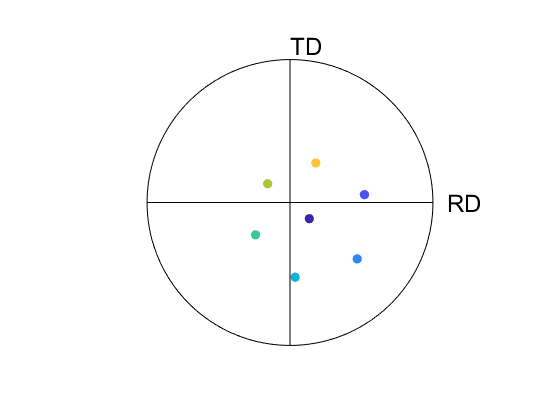

[ss,c_a] = define_SS_cart('Mg','Twin');

normals_input = [0 0 1];
for ii = 19:24
    normals_input = [normals_input; ss(1,:,ii)];
end


plot_on_PF(normals_input, [-50 -20 0], 'ND')

## simulate contraction twin in Jonas Acta 59(2011)2046 paper

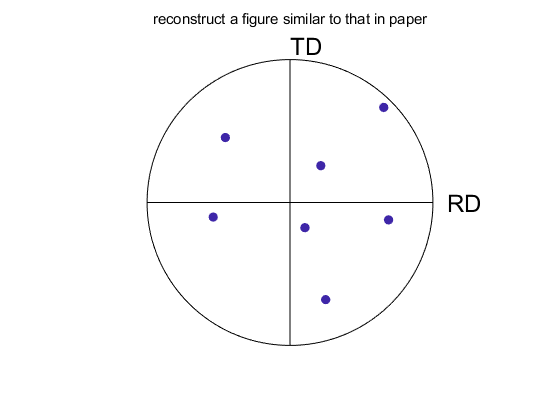

close all;

euler_p = [100 70 39];  % this is for the parent grain
eulers = euler_p;

for ii = 7:12
    euler_t = euler_by_twin(euler_p, ii, 'Mg');
    eulers = [eulers; euler_t];
end

% This plot is similar to that in the paper
plot_on_PF([0 0 1], eulers, 'ND');
title('reconstruct a figure similar to that in paper','fontweight','normal');

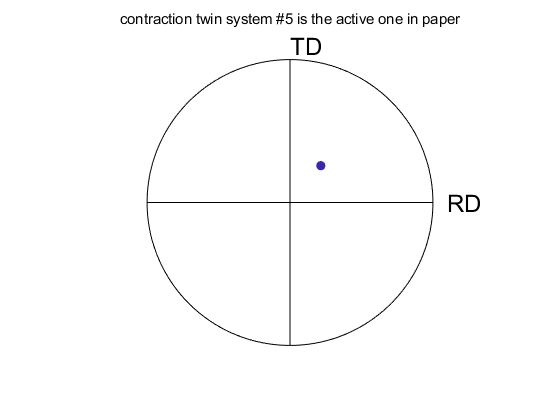


% So, contractin TS #5 is the one chosen in the paper, becuase the
% following plot gives the same position of the basal pole on the PF, as
% shown in the paper
plot_on_PF([0 0 1], eulers(5+1,:), 'ND');  
title('contraction twin system #5 is the active one in paper','fontweight','normal');



% So, we can calculate the theoretical trace direction, and display it. 
% Note: (1) here we need to use the euler of parent grain.  
% (2) the reference direction for this function 'trace_analysis_TiMgAl' is image convention, so x-right, y-down.  
[abs_schmid_factor, sorted_schmid_factor, burgersXY] = ...
    trace_analysis_TiMgAl(euler_p,[0 0 0],[0 0 0],[0 0 0; 0 1 0; 0 0 0],'Mg','ctwin');
disp(abs_schmid_factor);

    1.0000    0.1188  -80.0000    0.1736   -0.9848
    2.0000    0.1535  -80.0000    0.1736   -0.9848
    3.0000    0.0347  -80.0000    0.1736   -0.9848
    4.0000    0.4848  -12.8972   -0.9748    0.2232
    5.0000    0.2798   51.7008    0.6198    0.7848
    6.0000    0.2049   13.1007   -0.9740   -0.2267
    7.0000    0.3715   30.5999   -0.8607   -0.5090
    8.0000    0.3191  -17.0562    0.9560   -0.2933
    9.0000    0.1644   39.3698   -0.7731   -0.6343
   10.0000    0.4835  -40.6731    0.7584   -0.6517
   11.0000    0.1744   76.4352   -0.2345   -0.9721
   12.0000    0.1971  -14.4387    0.9684   -0.2493
   13.0000    0.0239   67.1472   -0.3884   -0.9215
   14.0000    0.4524   36.1065   -0.8079   -0.5893
   15.0000    0.2782   55.6614   -0.5641   -0.8257
   16.0000    0.0072  -70.3279    0.3366   -0.9416
   17.0000    0.3148  -26.9657    0.8913   -0.4535
   18.0000    0.1717  -15.1468    0.9653   -0.2613
   19.0000       NaN       NaN       NaN       NaN
   20.0000       NaN       NaN 


trace_dir = abs_schmid_factor(24+5,3);   % trace direction from x-dir to y-dir, which matches the figure in paper
Schmid_factor = abs_schmid_factor(24+5,2);  % schmid factor
disp(['the theoretical trace direction of contraction twin system #5 is: ',num2str(trace_dir)]);

the theoretical trace direction of contraction twin system #5 is: -40.6731


disp(['the theoretical SF of contraction twin system #5 is: ',num2str(Schmid_factor)]);

the theoretical SF of contraction twin system #5 is: 0.11294


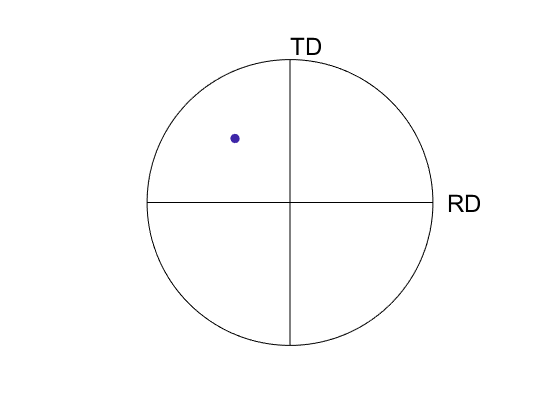


% Similarly, if we plot the pole of this contraction twin plan, and use
% eulre angle of the parent grain, it should be similar to the Guan paper
% i.e., connect the plot center and the pole, the line should be
% perpendicular to the twin trace direction.
ss = define_SS_cart('Mg','ctwin');
plot_on_PF(ss(1,:,24+5), euler_p, 'ND');